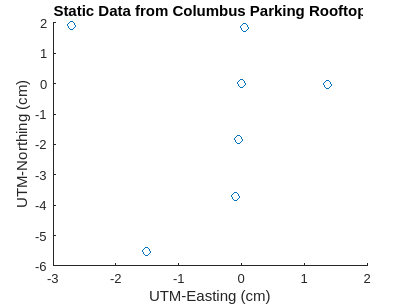


% OPEN DATA
sdataOpen = readmatrix('StatDataOpen.csv');
wdataOpen= readmatrix('walkRTK.csv');

sdataOpen(:,9) = sdataOpen(:,9) - sdataOpen(1,9);
sdataOpen(:,10) = sdataOpen(:,10) - sdataOpen(1,10);
stat_open_E = sdataOpen(:,9);
stat_open_N = sdataOpen(:,10);
scatter(100*stat_open_E,100*stat_open_N)
xlabel("UTM-Easting (cm)")
ylabel("UTM-Northing (cm)")
title("Static Data from Columbus Parking Rooftop")



easting_bound = max(stat_open_E) - min(stat_open_E);
northing_bound = max(stat_open_N) - min(stat_open_N);
error_bound = norm(easting_bound,northing_bound)

error_bound = 0.0407


% Moving Data Columbus Rooftop
min_w_easting_open = min(wdataOpen(:,9));
min_w_northing_open = min(wdataOpen(:,10));
wdataOpen(:,9) = wdataOpen(:,9) - wdataOpen(1,9);
wdataOpen(:,10) = wdataOpen(:,10) - wdataOpen(1,10);
walk_open_E = round(wdataOpen(:,9),4);
walk_open_N = round(wdataOpen(:,10),4);


% Getting corner points of the rectangle for best fit line
A = [-1.04194, -1.02997];
A = round(A,4);
B = [18.2751, 19.1439];
C = [22.4683, 14.7818];
D = [2.92828, -4.96066];
D = round(D,4);

% Best fit lines

i1 = find(walk_open_E == A(1))    % Getting indices of the corner points

i1 = 87

i2 = find(walk_open_E == B(1))

i2 = 36

i3 = find(walk_open_E == C(1))

i3 = 47

i4 = find(walk_open_E == D(1))

i4 = 80


arrayAB_E1 = walk_open_E(i1:99);
arrayAB_N1 = walk_open_N(i1:99);
arrayAB_E2 = walk_open_E(1:i2);
arrayAB_N2 = walk_open_N(1:i2);

arrayAB_E = cat(1,arrayAB_E1,arrayAB_E2);
arrayAB_N = cat(1,arrayAB_N1,arrayAB_N2);
fAB = fit(arrayAB_E,arrayAB_N,'poly1')

fAB =      Linear model Poly1:
     fAB(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.057  (1.054, 1.061)
       p2 =   -0.009216  (-0.03623, 0.0178)


arrayBC_E = walk_open_E(i2:i3);
arrayBC_N = walk_open_N(i2:i3);
fBC = fit(arrayBC_E,arrayBC_N,'poly1')

fBC =      Linear model Poly1:
     fBC(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     -0.9989  (-1.114, -0.8834)
       p2 =       37.07  (34.79, 39.35)


arrayCD_E = walk_open_E(i3:i4);
arrayCD_N = walk_open_N(i3:i4);
fCD = fit(arrayCD_E,arrayCD_N,'poly1')

fCD =      Linear model Poly1:
     fCD(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.045  (1.037, 1.053)
       p2 =       -8.59  (-8.702, -8.478)


arrayDA_E = walk_open_E(i4:i1);
arrayDA_N = walk_open_N(i4:i1);
fDA = fit(arrayDA_E,arrayDA_N,'poly1')

fDA =      Linear model Poly1:
     fDA(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     -0.9676  (-1.001, -0.9339)
       p2 =      -2.091  (-2.147, -2.036)

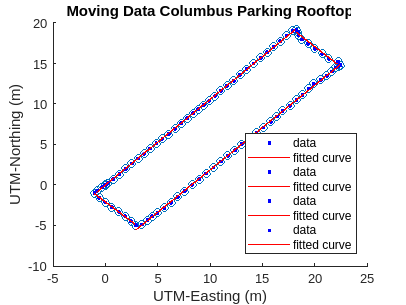


% Plotting walking open data
scatter(walk_open_E,walk_open_N)
hold on
plot(fAB,arrayAB_E,arrayAB_N)
plot(fBC,arrayBC_E,arrayBC_N)
plot(fCD,arrayCD_E,arrayCD_N)
plot(fDA,arrayDA_E,arrayDA_N)
hold off
legend('Location','southeast')
xlabel("UTM-Easting (m)")
ylabel("UTM-Northing (m)")
title("Moving Data Columbus Parking Rooftop")


% Deviation from the best fit line

errorAB = lineDist(fAB,arrayAB_E, arrayAB_N);
errorBC = lineDist(fBC,arrayBC_E, arrayBC_N);
errorCD = lineDist(fCD,arrayCD_E, arrayCD_N);
errorDA = lineDist(fDA,arrayDA_E, arrayDA_N);

rmsAB = rms(errorAB)

rmsAB = 0.0314

rmsBC = rms(errorBC)

rmsBC = 0.1247

rmsCD = rms(errorCD)

rmsCD = 0.0632

rmsDA = rms(errorDA)

rmsDA = 0.0235



rms_overall = (length(arrayAB_E)*rmsAB + length(arrayBC_E)*rmsBC + length(arrayCD_E)*rmsCD + length(arrayDA_E)*rmsDA)/length(walk_open_E)

rms_overall = 0.0542

% OCCLUDED DATA

sdataOcc = readmatrix('circle_stat.csv');
wdataOcc= readmatrix('circle_moving.csv');

circle_centre_E = sdataOcc(:,9) - sdataOcc(1,9);   % Circle Centre
circle_centre_N = sdataOcc(:,10) - sdataOcc(1,10);


circle_E = wdataOcc(:,9) - sdataOcc(1,9);          % Circle Circumference data
circle_N = wdataOcc(:,10) - sdataOcc(1,10);

theta = 0:0.01:2*pi;
[x,y,r,errorRMS] = circleFit(circle_E, circle_N)    % Calling circleFit function

x = -0.9271

y = 3.3727

r = 5.6626

errorRMS = 0.2827


x_coord = x + r*cos(theta)

x_coord =     4.7355    4.7352    4.7344    4.7329    4.7310    4.7284    4.7253    4.7216    4.7174    4.7126    4.7072    4.7013    4.6948    4.6877    4.6801    4.6719    4.6632    4.6539    4.6440    4.6336    4.6226    4.6111    4.5990    4.5864    4.5732    4.5595    4.5452    4.5303    4.5150    4.4990    4.4826    4.4656    4.4480    4.4299    4.4113    4.3922    4.3725    4.3523    4.3315    4.3103    4.2885    4.2662    4.2433    4.2200    4.1961    4.1718    4.1469    4.1215    4.0956    4.0692


y_coord = y + r*sin(theta)

y_coord =     3.3727    3.4294    3.4860    3.5426    3.5992    3.6557    3.7123    3.7688    3.8253    3.8817    3.9380    3.9944    4.0506    4.1068    4.1629    4.2189    4.2749    4.3307    4.3865    4.4422    4.4977    4.5532    4.6085    4.6637    4.7188    4.7737    4.8285    4.8831    4.9376    4.9920    5.0461    5.1002    5.1540    5.2077    5.2611    5.3144    5.3675    5.4204    5.4731    5.5256    5.5779    5.6299    5.6817    5.7333    5.7847    5.8358    5.8866    5.9373    5.9876    6.0377


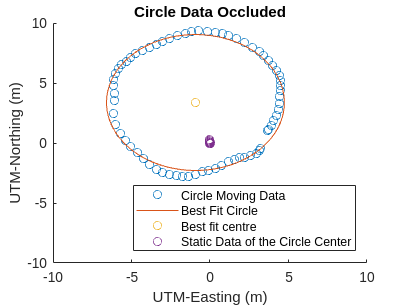


% Plotting occluded data

scatter(circle_E, circle_N, "DisplayName","Circle Moving Data")
hold on
plot(x_coord,y_coord,"DisplayName","Best Fit Circle")
scatter(x,y,"DisplayName","Best fit centre")
scatter(circle_centre_E,circle_centre_N, "DisplayName","Static Data of the Circle Center")
hold off
xlabel("UTM-Easting (m)")
ylabel("UTM-Northing (m)")
title("Circle Data Occluded")
legend("Location","southeast")
xlim([-10,10])
ylim([-10,10])

xlim([-10.0 10.0])
ylim([-10.0 10.0])

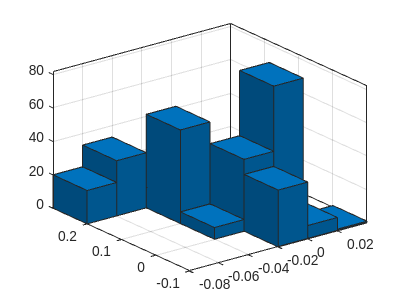


histogram2(circle_centre_E,circle_centre_N)

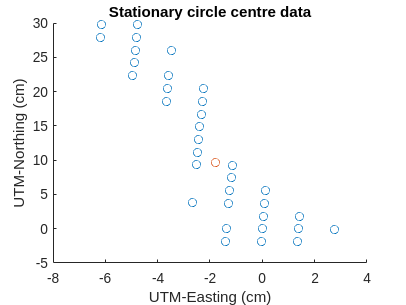

scatter(100*circle_centre_E,100*circle_centre_N)
xlabel("UTM-Easting (cm)")
ylabel("UTM-Northing (cm)")
title("Stationary circle centre data")
hold on
scatter(mean(100*circle_centre_E),mean(100*circle_centre_N))
hold off


% Analysis

easting_bound = max(circle_centre_E) - min(circle_centre_E);
northing_bound = max(circle_centre_N) - min(circle_centre_N);
value_bound = norm(easting_bound,northing_bound)

value_bound = 0.0893

MeanE = mean(circle_centre_E); % Mean of the occluded static data
MeanN = mean(circle_centre_N);

% Rough estimate of the offset in centimeters. 
distance = norm(100*(MeanE-x),100*(MeanN-y))

distance = 90.9095